# Testing (scroll down and skip this for simulation loop)

Otherwise run here to simulate a uav mission

### TO DO

- parallelize digitaltwin execution, gather total flight times, create distribution. this is RUL for next true system flight

### Load paths and variables

addpath(genpath(pwd));
load_db_params;
conn = database(datasource_name, user_name, password);
load_trajectory;
load_true_workspace;


### Simulate

Mode Selection 

- true system - nominal

- true system - degraded

- digital twin - nominal

- digital twin - degraded

sys = "TrueSystem";
%sys = "DigitalTwin";

mode = "Nominal";
%mode = "Degraded";

% degraded_level needs fixed to reflect the non-accelerated degradation
% profiles, before 11 was really degraded, now it is hardly
degraded_level = 11;

Degraded or Nominal

if mode == "Degraded"
    battery.R0=rdeg(degraded_level);
    battery.Q=qdeg(degraded_level);
    Motor2.Req=mdeg(degraded_level);
    Motor4.Req=mdeg(degraded_level);
else
    battery.R0=rdeg(1);
    battery.Q=qdeg(1);
    Motor2.Req=mdeg(1);
    Motor4.Req=mdeg(1);
end

if sys == 'TrueSystem'
    octomodel.sampletime = .025;
    disp('true system simulation');
    load_system('truesystem');
    tic
    out = sim('truesystem.slx');
    toc
else
    batterytwin = battery;
    Motortwin2 = Motor2;
    Motortwin4 = Motor4;
    octomodel.sampletime = .05;
    load_system('digitaltwin1c');
    tic
    out = sim('digitaltwin1c.slx');
    toc
end

true system simulation


Elapsed time is 37.206121 seconds.


rul = flight_time.Data(end)

rul = 1.9729

## Write data to database

start = datetime(now, 'ConvertFrom', 'datenum');
start = dateshift(start, 'start', 'second');
stop = start + seconds(rul*60);
mission_id = table2array(select(conn, 'select id from mission_tb mt order by id desc limit 1;'));
if isempty(mission_id)
    mission_id = 1;
else
    mission_id = mission_id + 1;
end

write_mission_data;
write_battery_data;
write_flight_data;

## Plot Path

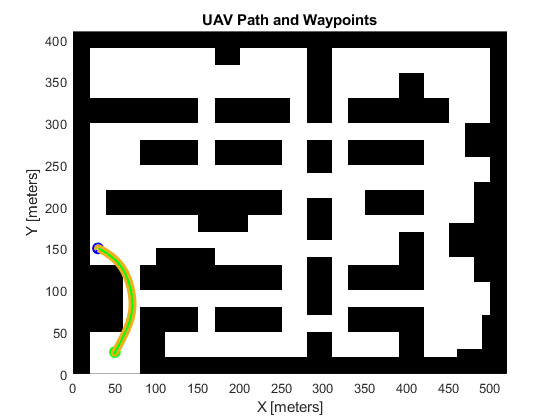

f1 = figure(1); clf;
hold on;
show(map);
plot(pos_observed.Data(1,1), pos_observed.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'bo', 'LineWidth', 3); 
end
plot(xRefPoints(:,2), yRefPoints(:,2), 'linewidth', 6);
%plot(pos_actual.Data(:,1), pos_actual.Data(:,2), 'linewidth', 6);
plot(pos_observed.Data(:,1), pos_observed.Data(:,2),'g--', 'linewidth', .5);
if ~any(stop_code.Data(:,3))
    plot(pos_observed.Data(end, 1), pos_observed.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3);
end
hold off;
title("UAV Path and Waypoints");

## Euclidean Position Error

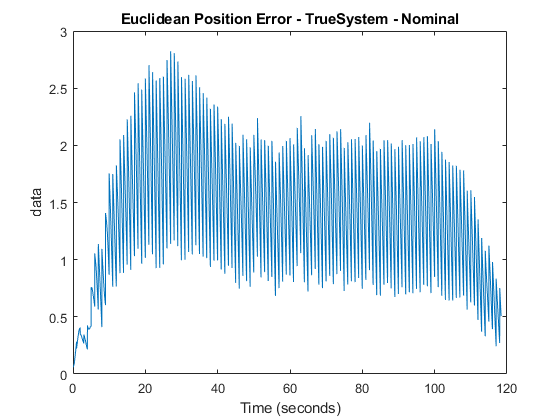

f2 = figure(2); clf;
plot(euclidean_pos_err);
ttl = sprintf("%s - %s - %s", 'Euclidean Position Error', sys, mode);
title(ttl);

## Voltage and SOC Plot

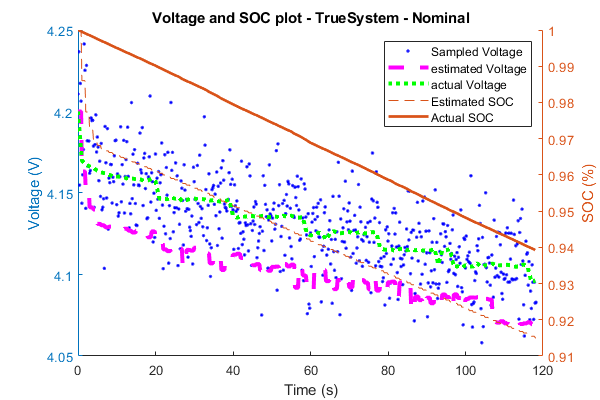

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'b.',  "DisplayName", "Sampled Voltage");
plot(battery_observed.Time(:), battery_observed.Data(:,2), 'm', 'linewidth', 3, "DisplayName", "estimated Voltage");
plot(battery_actual.Time(:), battery_actual.Data(:,1), 'g', 'linewidth', 3, "DisplayName", "actual Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,3), '--', "DisplayName", "Estimated SOC");
plot(battery_actual.Time(:), battery_actual.Data(:,2),'-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
ttl = sprintf("%s - %s - %s", 'Voltage and SOC plot', sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

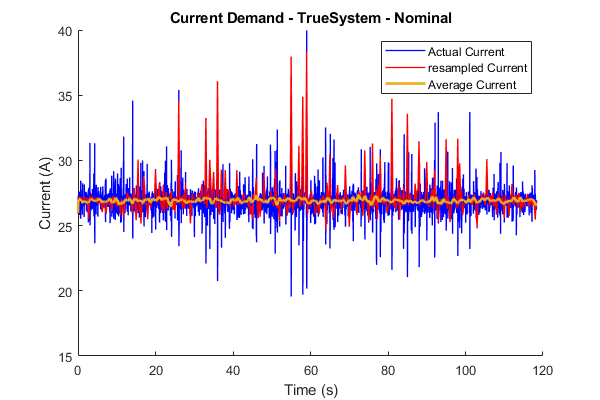

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(current.Time(:,1), current.Data(:,1), 'b', 'linewidth', 1, "DisplayName", "Actual Current");
plot(current_rs.Time(:), current_rs.Data(:,1), 'r', 'linewidth', 1, "DisplayName", "resampled Current");
plot(downsample(current.Time(:,1), 3),smoothdata(downsample(current.Data(:,1), 3), 'rlowess', 20), 'linewidth', 2, "DisplayName", "Average Current");
hold off;
title(sprintf("%s - %s - %s", 'Current Demand', sys, mode));
xlabel("Time (s)");
ylabel("Current (A)");
ylim([15 40]);
legend();

# *********************************************************************************************************************

# Simulation Loop 

# *********************************************************************************************************************

## Start here!

## load main workspace 


addpath(genpath(pwd));
load_db_params;
conn = database(datasource_name, user_name, password);
load_true_workspace;


## Initialize some variables

% counter for each true system simulation
true_ctr = 1;

% for poly fitting
lookback = 6;

% how far into the future to look
horizon = 3;

% number of missions (can be oversized)
n_missions = 100;

% keep track of delta over time
% number of missions, 3 degradation parameters, 2 coefficients to save
% (slope & intercept)
polys = zeros(n_missions, 3, 2);

% keep track of degradation parameter values for poly fitting
q_deg = zeros(n_missions, 1);
r_deg = zeros(n_missions, 1);
m_deg = zeros(n_missions, 1);

## Main Loop

% loop 
% accelerated is 80
% normal is 300
% test is 3
for true_ctr = 1:1
    octomodel.sampletime = true_sample_rate;
    tic
    sim('truesystem.slx');
    toc

Elapsed time is 40.205367 seconds.


Analyzing and transferring files to the workers ...done.


Elapsed time is 16.238387 seconds.


Dot indexing is not supported for variables of this type.

###         update variance

    r_var = battery_observed.Data(end, 6);
    q_var = battery_observed.Data(end, 8);
    m_var = motors.Data(2, 4);
    

### **        sample the degradation parameters based on the variance**

    R0i = normrnd(rdeg(true_ctr), r_var);
    Qi  = normrnd(qdeg(true_ctr), q_var);
    RMi = normrnd(mdeg(true_ctr), m_var);   

###         assign the degradation parameters to the true system

    battery.R0 = R0i;
    battery.Q = Qi;
    Motor2.Req = RMi;

###         define placeholder variables

        1st attempt was a matrix of where each row is a given run. this created memory problem. now just create a single vector for each, save the vector, then clear it. repeat.

    twin_flight_times = zeros(1,48);
    twin_voltages = zeros(1,48);
    twin_socs = zeros(1,48);
    twin_r0s = zeros(1,48);
    twin_qs = zeros(1,48);
    twin_mot_res = zeros(1,48);
    twin_pos_errs = zeros(1,48);
    twin_deg_info = zeros(6,48);

###         now simulate digital twin 48 times (12 cores x 4 iterations)

    octomodel.sampletime = twin_sample_rate;
    numRuns = 12;
    idx_ctr = 1;
    %clear('twin_pos_errs', 'twin_mot_res', 'twin_qs', 'twin_r0s', 'twin_socs', 'twin_voltages', 'twin_flight_times', 'S');

###           repeat 4 times to achieve 48 samples

    for twin_ctr=1:4
        tic
        for n = 1:numRuns
            in(n) = Simulink.SimulationInput("digitaltwin1c");
        end
        tic    

###                 creates 12 parallel workers (numRuns = 12) and executes the simulations

        out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()parallel_initializer_handler(i, lookback, horizon, r_var, q_var, m_var, twin_sample_rate));
        toc
        for run_ctr = 1:numRuns

###                         get the output from each parallel worker

            times(run_ctr) = out(run_ctr).flight_time.Data(end);
            vs(run_ctr) = out(run_ctr).battery_actual.Data(end, 1);
            socs(run_ctr) = out(run_ctr).battery_actual.Data(end, 2);
            r0s(run_ctr) = out(run_ctr).battery_actual.Data(end, 3);
            qs(run_ctr) = out(run_ctr).battery_actual.Data(end, 6);
            ms(run_ctr) = out(run_ctr).motors.Data(end, 1);
            errs(run_ctr) = mean(out(run_ctr).euclidean_pos_err);
            %sprintf("err: %f", errs(run_ctr)) 
        end
        

###                 combine the output from each loop to form arrays of (1,48) size for each parameter

        %sprintf("true_ctr: %d\tidx_ctr: %d\tr*t: %d \n", true_ctr, idx_ctr, run_ctr*twin_ctr)
        twin_flight_times(1,idx_ctr:twin_ctr*run_ctr) = times; 
        twin_voltages(1,idx_ctr:twin_ctr*run_ctr) = vs;
        twin_socs(1,idx_ctr:twin_ctr*run_ctr) = socs;
        twin_r0s(1,idx_ctr:twin_ctr*run_ctr) = r0s;
        twin_qs(1,idx_ctr:twin_ctr*run_ctr) = qs;
        twin_mot_res(1,idx_ctr:twin_ctr*run_ctr) = ms;
        twin_pos_errs(1,idx_ctr:twin_ctr*run_ctr) = errs;

###                  increment the counter for data concatenation

        idx_ctr = twin_ctr * numRuns + 1;
    end 

###          save the parameters from the current stochastic simulation run

    S.(sprintf('twin_flight_times_%d', true_ctr)) = twin_flight_times;
    save(sprintf('G:\\matlab\\twin_flight_times_%d.mat', true_ctr), '-struct', 'S');
    clear S;
    
    S.(sprintf('twin_voltages_%d', true_ctr)) = twin_voltages;
    save(sprintf('G:\\matlab\\twin_voltages_%d.mat', true_ctr), '-struct', 'S')
    clear S;
    
    S.(sprintf('twin_socs_%d', true_ctr)) = twin_socs;
    save(sprintf('G:\\matlab\\twin_socs_%d.mat', true_ctr), '-struct', 'S')
    clear S;
    
    S.(sprintf('twin_r0s_%d', true_ctr)) = twin_r0s;
    save(sprintf('G:\\matlab\\twin_r0s_%d.mat', true_ctr), '-struct', 'S')
    clear S;
    
    S.(sprintf('twin_qs_%d', true_ctr)) = twin_qs;
    save(sprintf('G:\\matlab\\twin_qs_%d.mat', true_ctr), '-struct', 'S')
    clear S;
    
    S.(sprintf('twin_mot_res_%d', true_ctr)) = twin_mot_res;
    save(sprintf('G:\\matlab\\twin_mot_res_%d.mat', true_ctr), '-struct', 'S')
    clear S;
    
    S.(sprintf('twin_pos_errs_%d', true_ctr)) = twin_pos_errs;
    save(sprintf('G:\\matlab\\twin_pos_errs_%d.mat', true_ctr), '-struct', 'S')
    clear S;
    
    %S.(sprintf('deg_params_$d', true_ctr)) = deg_params;

###         do some checks on when to stop the simulation

    if mean(twin_flight_times(1,:)) < 15
        disp('rul is < 10 minutes. Ending experiment.');
        break;
    end
    
    if(any(out(1,2).stop_code.Data(:,2)) == 1)
        sprintf('crash on mission %d', true_ctr)
        break;
    end
    

###         clear the temporary variables

    %clear('twin_pos_errs', 'twin_mot_res', 'twin_qs', 'twin_r0s', 'twin_socs', 'twin_voltages', 'twin_flight_times', 'S');
        
end

parallel_initializer_handler(i, lookback, horizon, r_var, q_var, m_var, twin_sample_rate)

% disp(twin_flight_times(true_ctr,:))
% disp(twin_voltages(true_ctr,:))
% disp(twin_socs(true_ctr,:))
% disp(twin_r0s(true_ctr,:))
% disp(twin_qs(true_ctr,:))
% disp(twin_mot_res(true_ctr,:))
% disp(twin_pos_errs(true_ctr,:))

mean(twin_flight_times(true_ctr,:))

# END OF PROGNOSTICS CODE

# Scratch paper below

f1 = figure(1); clf;
hold on;
x_vals = 14:.01:23;
pd = fitdist(twin_flight_times_1', 'Normal');
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2,  'DisplayName', '1st run');
pd = fitdist(twin_flight_times_2', 'Normal');
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2,  'DisplayName', '2nd run');
pd = fitdist(twin_flight_times_3', 'Normal');
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2, 'DisplayName', '3rd run');
% pd = fitdist(twin_flight_times_4', 'Normal');
% y = pdf(pd, x_vals);
% plot(x_vals, y, 'LineWidth', 2, 'DisplayName', '4th run');
hold off;
title("RUL plot");
xlabel("Time (S)");
ylabel("Probability");
legend();

pd = fitdist(twin_pos_errs(1,:)', 'Normal');
x_vals = 1.5:.001:2;
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2);

pd = fitdist(twin_flight_times(1,:)', 'Normal');
x_vals = 10:.1:25;
y = pdf(pd, x_vals);
plot(x_vals, y, 'LineWidth', 2);


## Parallel Testing

- get average runtime of of iteration without parallelism

load_system('digitaltwin1c');
runs = 5;
tic
for i = 1:runs
    load_fresh_workspace;
    octomodel.sampletime = .05;
    sim("digitaltwin1c.slx");
    rul = flight_time.Data(end)
end
t2 = toc
t2/runs

Parallel testing with parameters in setup function

arg1 = .03;
%evalin('base', 'partest.m')
for i = 1:13
    in(i) = Simulink.SimulationInput('digitaltwin1c');
end

out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_parallel_workspace(1,2,3,4,5,6,7));

for i = 1:5
    res = out(i).res.Data(1,1)
   
end

numRuns = 6;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace(i, r_var, q_var, m_var));
toc


for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    r0s(i) = out(i).battery_actual.Data(end, 3);
    qs(i) = out(i).battery_actual.Data(end, 6);
    ms(i) = out(i).motors.Data(end, 1);
end
disp(times)
disp(r0s)
disp(socs)
disp(qs)
avg_time = sum(times)/length(times)

% n_missions = 100;
% i = 1;
% lookback = 6;
% horizon = 3;
% r_var =.0029;
% q_var = .98;
% m_var = .002;
% twin_sample_rate = .05;
% parallel_initializer_handler(i, lookback, horizon, r_var, q_var, m_var, twin_sample_rate)
evalin('base', sprintf('parallel_initializer_handler(%d, %d, %d, %f, %f, %f, %f)', 1, 6, 3, .0029, .98, .002, .05))
% t = linspace(1, n_missions, n_missions);
% yfinal = exp(-.05*t);
% plot(t,yfinal,'c*')










